# Working with data in MATLAB

# W6 - Topic 2 - Exercise 2

Imagine you are analyzing air traffic control data for NAV Canada. They've asked you to analyze one single moment in time of radar data on a busy morning around Toronto.

## Data tables

### Loading tabular data

While flying, airplanes broadcast a "squawk code", a 4 digit number identifying the plane that appears on radar screens. But most of the time, we want to use that code to display other information about the flight (ie. flight number, airplane type), and because we're lazy, we're going to tell MATLAB to do the work for us!

**First, let's load in data about the location of planes and their squawk code.**

- Use `readtable` to load `radardata.csv `from` https://raw.githubusercontent.com/dtxe/mat188_datasets/main/radardata.csv`

- Store this into a variable named `radardata`.

radardata = readtable('https://raw.githubusercontent.com/dtxe/mat188_datasets/main/radardata.csv');    % <<< complete this line

Whenever we load data in, it's always good to double check that it is loaded properly. We can display the first few rows using the `head` command.

disp(head(radardata));    % <<< complete this line

    squawk    angle_receiver    distance_receiver
    ______    ______________    _________________

     2463         178.43              38782      
     2070        -167.87              37392      
     7792        -141.11              45245      
     3317        -137.13              45721      
     5485        -127.98              43035      
     9633        -178.05              25334      
     7291         124.96              43420      
     3484         126.92              35324      



**Next, let's load in data about flights and their corresponding squawk codes.** 

- Load `flightdata.csv` from `https://raw.githubusercontent.com/dtxe/mat188_datasets/main/flightdata.csv`

- ... into the variable `flightdata` and ...

- ... display the last few rows using the `tail` command to ensure the data is properly loaded.

%%% complete the following code %%%
flightdata = readtable('https://raw.githubusercontent.com/dtxe/mat188_datasets/main/flightdata.csv');
disp(head(flightdata));

    squawk       type       weight    origin     destination
    ______    __________    ______    _______    ___________

     4407     {'CRJ900'}    32814     {'YYC'}      {'YYZ'}  
     8153     {'A220'  }    60001     {'YUL'}      {'YYZ'}  
     4149     {'A220'  }    59617     {'YQX'}      {'YYZ'}  
     9633     {'E195'  }    13400     {'YQX'}      {'YYZ'}  
     5924     {'E195'  }    13346     {'LGA'}      {'YYZ'}  
     4063     {'Q300'  }    18809     {'LFT'}      {'YYZ'}  
     8358     {'Q300'  }    19192     {'YEG'}      {'YYZ'}  
     9018     {'A220'  }    60129     {'LFT'}      {'YYZ'}  



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Sorting

The flight data is looking a little haphazard. Suppose we want to find the biggest planes because we need to pay special attention to them.

Let's use the `sortrows` function to **sort the **`flightdata`** table** by the plane's weight in *descending order*.

sorted_flightdata = sortrows(flightdata,"weight","descend");   % <<< complete this line

Next, display the first 15 rows in the sorted table.

disp(sorted_flightdata,15) % <<< complete this line

    squawk       type         weight      origin     destination
    ______    __________    __________    _______    ___________

     2247     {'A330'  }    1.9082e+05    {'YVR'}      {'YYZ'}  
     3484     {'A330'  }    1.9073e+05    {'YEG'}      {'YYZ'}  
     7761     {'A330'  }    1.9057e+05    {'LGA'}      {'YYZ'}  
     3191     {'A330'  }    1.9042e+05    {'BWI'}      {'YYZ'}  
     7291     {'A330'  }    1.9038e+05    {'YUL'}      {'YYZ'}  
     6798     {'A330'  }    1.9036e+05    {'MIA'}      {'YYZ'}  
     2343     {'B737'  }         69240    {'FLL'}      {'YYZ'}  
     9637     {'B737'  }         69215    {'TPA'}      {'YYZ'}  
     7384     {'B737'  }         69148    {'YUL'}      {'YYZ'}  
     2769     {'B737'  }         68715    {'JFK'}      {'YYZ'}  
     3295     {'B737'  }         68485    {'YUL'}

### Combining information from multiple tables

Notice that the radar data contains location information but no airplane information, while the flight data table contains airplane information but not their location. Now, let's harness the power of MATLAB to combine this information together into one table!

Using the `join` command, **combine **`radardata`** and **`flightdata`** using the squawk code as the *****key.*** Store the results into `enhanced_radardata`.

enhanced_radardata = join(radardata,flightdata,"Keys","squawk");   % <<< complete this line

Let's take a look at the combined data using the `display` command.

display(enhanced_radardata);

enhanced_radardata = 37×7 table
    squawk    angle_receiver    distance_receiver       type         weight      origin     destination
    ______    ______________    _________________    __________    __________    _______    ___________

     2463         178.43              38782          {'Q300'  }         18915    {'CVG'}      {'YYZ'}  
     2070        -167.87              37392          {'CRJ900'}         33119    {'YEG'}      {'YYZ'}  
     7792        -141.11              45245          {'E195'  }         13305    {'YOW'}      {'YYZ'}  
     3317        -137.13              45721          {'A220'  }         60017    {'JFK'}      {'YYZ'}  
     5485        -127.98              43035          {'A220'  }         60348    {'FLL'}      {'YYZ'}  
 

Notice how MATLAB used a common identifier / linking variable / the *key*, to cross-reference and combine the data from both tables together. *This is a very powerful tool!*

### Selecting a subset of data

You can index a table in a similar manner to any MATLAB array.

Now it's your turn! **Select all planes larger than 50 000 kg** from `enhanced_radardata` and store them into the variable `bigplanes`, and store the rest into the variable `smallplanes`.

%%% complete the following code %%%
bigplanes = enhanced_radardata(enhanced_radardata.weight > 50000, :)

bigplanes = 22×7 table
    squawk    angle_receiver    distance_receiver      type        weight      origin     destination
    ______    ______________    _________________    ________    __________    _______    ___________

     3317        -137.13              45721          {'A220'}         60017    {'JFK'}      {'YYZ'}  
     5485        -127.98              43035          {'A220'}         60348    {'FLL'}      {'YYZ'}  
     7291         124.96              43420          {'A330'}    1.9038e+05    {'YUL'}      {'YYZ'}  
     3484         126.92              35324          {'A330'}    1.9073e+05    {'YEG'}      {'YYZ'}  
     3295        -114.34              39541          {'B737'}         68485    {'YUL'}      {'YYZ'}  
     4149        -117.75

smallplanes = enhanced_radardata(enhanced_radardata.weight < 50000, :)

smallplanes = 15×7 table
    squawk    angle_receiver    distance_receiver       type       weight    origin     destination
    ______    ______________    _________________    __________    ______    _______    ___________

     2463         178.43              38782          {'Q300'  }    18915     {'CVG'}      {'YYZ'}  
     2070        -167.87              37392          {'CRJ900'}    33119     {'YEG'}      {'YYZ'}  
     7792        -141.11              45245          {'E195'  }    13305     {'YOW'}      {'YYZ'}  
     9633        -178.05              25334          {'E195'  }    13400     {'YQX'}      {'YYZ'}  
     7117         140.27              15276          {'E195'  }    12960     {'BWI'}      {'YYZ'}  
     5924        -129.02            

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Polar plots

Using the enhanced radar data, let's visualize the position of all the planes.

### Data check!!

Look up the MATLAB documentation for the polarscatter command.

                    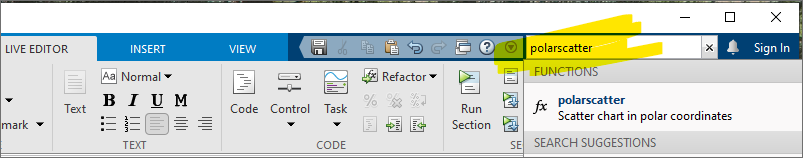

What units does it expect the data (specifically the angle data) to be in? 

**Radians**

What units are available in our dataset?

**Degrees**

**If the units are not appropriate**, convert them below. These functions may be useful.

%%% your code here, if necessary %%%
enhanced_radardata.angle_receiver = deg2rad(enhanced_radardata.angle_receiver);
bigplanes.angle_receiver = deg2rad(bigplanes.angle_receiver);
smallplanes.angle_receiver = deg2rad(smallplanes.angle_receiver);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Basic polar plots

Because each plane is an individual data point, it makes more sense to visualize them in a scatterplot. 

- Using the `polarscatter` command, **plot the location of each plane** relative to the radar transmitter using the data from `enhanced_radardata`. 

- Assume the radar transmitter is located at the origin. ie. $\left(\theta =0,r=0\right)$

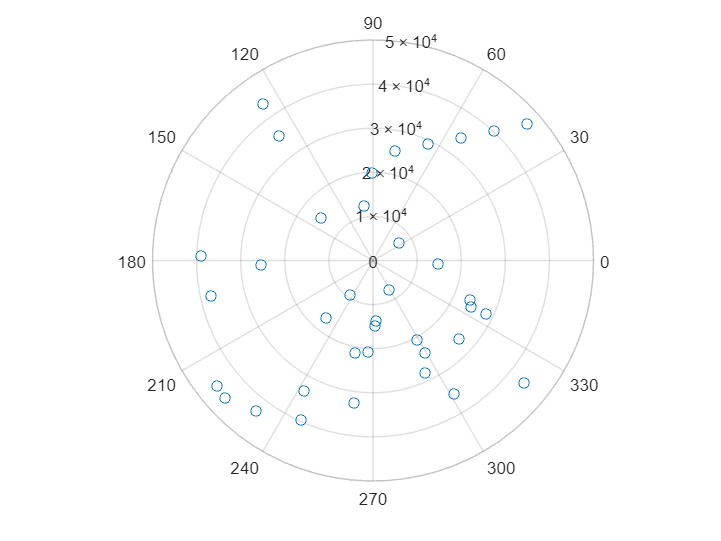

figure;   % create a new figure

%%% complete the following code %%%

polarscatter(enhanced_radardata.angle_receiver,enhanced_radardata.distance_receiver)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### Polar plots with legend

As we mentioned above, we want to pay special attention to big planes so let's plot them in a different colour.

Using the `hold` and `polarscatter` commands and the `bigplanes` and `smallplanes` subsetted data tables you obtained above, **visualize big planes with a different shape and in a different colour**.

figure;    % create a new figure

%%% enter your code below %%%
polarscatter(bigplanes.angle_receiver,bigplanes.distance_receiver,20,"red","filled")
hold

Current plot held


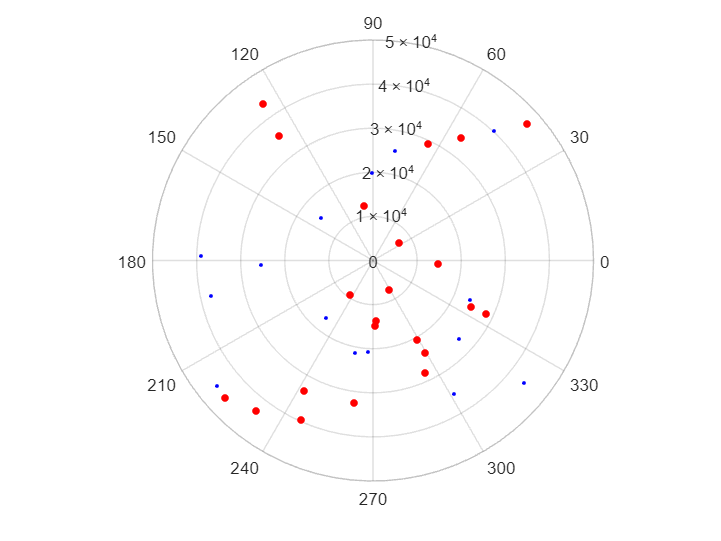

polarscatter(smallplanes.angle_receiver,smallplanes.distance_receiver,5,"blue","filled")

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Polar coordinates and transformations

Uh oh, based on our plot above, it looks like some of the big planes might be too close to each other! Big planes must stay at least 9260 m apart, but it's hard to tell for sure if we are only looking at the graph.

Let's use the power of math to calculate the distance between them and check if all the big planes are abiding by the minimum separation distance. However, our data is currently in polar coordinates and computing the (Cartesian) distance is rather complicated. To make things easier, let's convert the plane positions into Cartesian coordinates first. 

Using the `pol2cart` command, **convert the location of the big planes into Cartesian coordinates** and store the results into `bigplanes.x` and `bigplanes.y`.

[bigplanes.x, bigplanes.y] = pol2cart(bigplanes.angle_receiver,bigplanes.distance_receiver);   % <<< complete this line
pol2cart(-2.3934,45721)

ans = -3.3510e+04

disp(head(bigplanes))   % print the table just to check

    squawk    angle_receiver    distance_receiver      type        weight      origin     destination       x          y   
    ______    ______________    _________________    ________    __________    _______    ___________    _______    _______

     3317        -2.3934              45721          {'A220'}         60017    {'JFK'}      {'YYZ'}       -33510     -31104
     5485        -2.2336              43035          {'A220'}         60348    {'FLL'}      {'YYZ'}       -26480     -33923
     7291          2.181              43420          {'A330'}    1.9038e+05    {'YUL'}      {'YYZ'}       -24883      35583
     3484         2.2151              35324          {'A330'}    1.9073e+

### Plot to confirm

Let's check that our conversion worked properly.

**Make a scatter plot using **`bigplanes.x`** and **`bigplanes.y`** in Cartesian coordinates.**

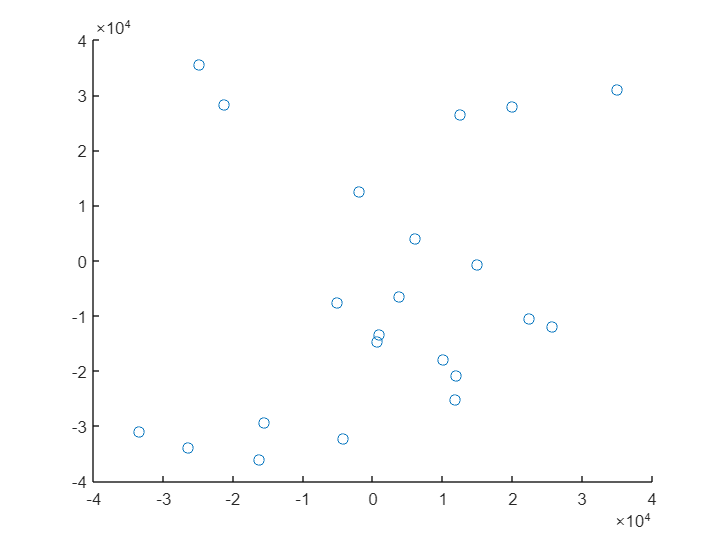

%%% your code here %%%
figure
scatter(bigplanes.x,bigplanes.y)


%%%%%%%%%%%%%%%%%%%%%%

### Cartesian distances

Next, using a nested for-loop, compute the distances between each pair of big planes and store the *adjacency matrix* into variable `separation_dists`.

        Hint: $d=\sqrt{\Delta x^2 +\Delta y^2 }$

num_big_planes = height(bigplanes);   % how many big planes do we have
separation_dists = zeros(num_big_planes, num_big_planes);    % initialize adjacency matrix

% loop through each pair of planes
for plane1 = 1:num_big_planes
    for plane2 = 1:num_big_planes

        separation_dists(plane1, plane2) = sqrt((bigplanes(plane1,:).x-bigplanes(plane2,:).x)^2+(bigplanes(plane1,:).y-bigplanes(plane2,:).y)^2);     % <<< complete this line
        
    end
end

### Summarizing an array

Finally, using the `any` command, **check if any of the separation distances are under 1.5 nautical miles (2778 m), but greater than 0 m** because each plane is by definition, 0 m from itself.

        Hint: According to the MATLAB documentation, the `any` command usually operates along the first array dimension (ie. down each column), but we want to look throughout the entire matrix. Use the `'all'` argument to flatten the matrix.

%%% your code here %%%
dist_violations = any(separation_dists > 2278, 'all');
any_sep_dist_violations = any(dist_violations, 'all');
%%%%%%%%%%%%%%%%%%%%%%